# EE352 Automatic Control Assignment - Question 3

**Iterative Reduction of dd**

**Student Name:** Perera J.D.T.

**Registration Number:** E/21/291

## 1. Define System Parameters

clc;
clear;
close all;

% User Parameters (DOB: 2003-01-18)
yy = 3;
mm = 1;
dd = 18;
SE = 291; 

fprintf('Parameters: yy=%d, mm=%d, dd=%d, SE=%d\n', yy, mm, dd, SE);

Parameters: yy=3, mm=1, dd=18, SE=291


## Q3: Effect of Stiffness (dd) reduction

We will reduce the value of $dd$ in 10 equal steps to zero.

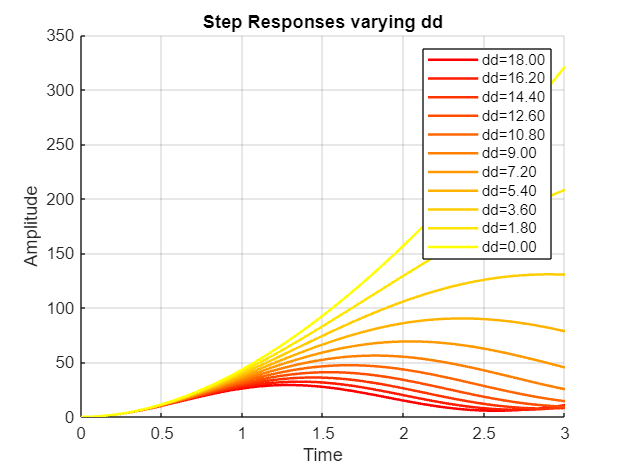

num = [SE];
dd_values = linspace(dd, 0, 11); % Range from dd down to 0

% Prepare Figures
fig_resp = figure('Name', 'Q3: Step Responses');
hold on; 
title('Step Responses varying dd'); 
xlabel('Time'); ylabel('Amplitude');

fig_poles = figure('Name', 'Q3: Pole Locations');
hold on; 
title('Pole Locations varying dd'); 
xlabel('Real Axis'); ylabel('Imaginary Axis');
grid on; xline(0,'k--'); yline(0,'k--');

colors = autumn(length(dd_values));

% Iteration Loop
for i = 1:length(dd_values)
    curr_dd = dd_values(i);
    curr_den = [yy, mm, curr_dd];
    
    % Create temp TF
    G_temp = tf(num, curr_den);
    
    % Plot Step Response
    figure(fig_resp);
    [y, t] = step(G_temp, 3);
    plot(t, y, 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('dd=%.2f', curr_dd));
    
    % Plot Poles
    figure(fig_poles);
    p = roots(curr_den);
    plot(real(p), imag(p), 'o', 'Color', colors(i,:), 'LineWidth', 2, 'MarkerSize', 8, ...
        'DisplayName', sprintf('dd=%.2f', curr_dd));
end

figure(fig_resp); legend show; grid on;

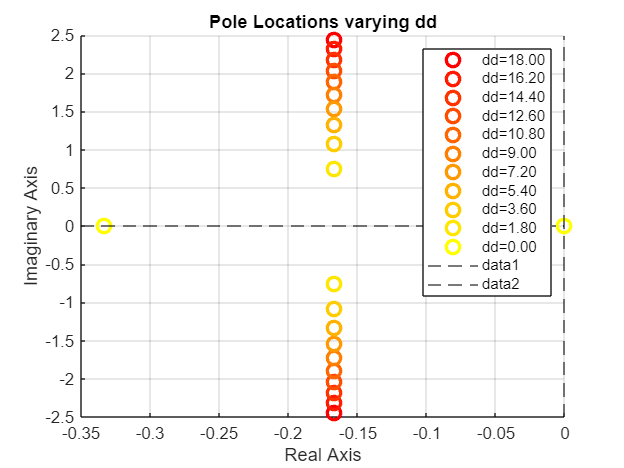

figure(fig_poles); legend show;

## Q3c: Explanation of Result for dd = 0

**Observation:**

As $dd$ reduces, the natural frequency of the system changes.

**At dd = 0:** The denominator becomes $yy \cdot s^2 + mm \cdot s = s(yy \cdot s + mm)$. One pole is located exactly at the origin ($s=0$) and the other at $s = -mm/yy$. A pole at the origin acts as a pure integrator. Consequently, the step response becomes a ramp function (unbounded growth over time).